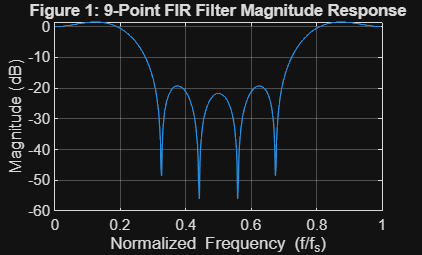

% Experiential DSP Homework 4
N = 9;
fc = 0.25;
n = 0:(N-1);
alpha = (N-1)/2;

% 9 Pt FIR Impulse
h = sinc(2 * fc * (n - alpha));

% Normalized Impulse Response
h_normalized = h / sum(h);

N_fft = 512;
H = fft(h_normalized, N_fft);
f = (0:N_fft - 1) / (N_fft);

% figure 1
figure(1);
plot(f, 20*log10(abs(H)));

% Added labels
title('Figure 1: 9-Point FIR Filter Magnitude Response');
xlabel('Normalized Frequency (f/f_s)');
ylabel('Magnitude (dB)');

grid on;

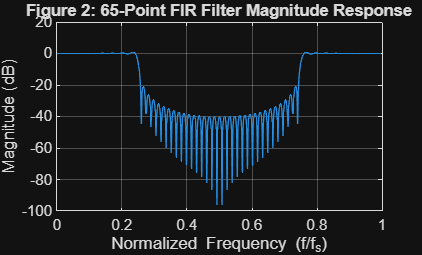

% Code block for N = 65
N2 = 65;
n2 = 0:(N2-1);
alpha2 = (N2-1)/2;

% 65-point impulse response
h2 = sinc(2 * fc * (n2 - alpha2));
h2_normalized = h2 / sum(h2);

H2 = fft(h2_normalized, N_fft);

% figure 2
figure(2);
plot(f, 20*log10(abs(H2)));

% Added labels
title('Figure 2: 65-Point FIR Filter Magnitude Response');
xlabel('Normalized Frequency (f/f_s)');
ylabel('Magnitude (dB)');

grid on;